# Homework 4

Jonathan Sanchez

RBE 3001

10/08/2018

a) fwd kinematics

syms q1(t) q2(t) l1 l2 lc1 lc2 m1 m2 mL dq1(t) dq2(t) ddq1(t) ddq2(t)
symVars = [q1(t), q2(t), l1, l2, lc1, lc2, m1, m2, mL, dq1(t), dq2(t), ddq1(t), ddq2(t)];

T01 = [ cos(q1(t)), -sin(q1(t)), 0, l1*cos(q1(t));
        sin(q1(t)), cos(q1(t)),  0, l1*sin(q1(t));
        0,             0,  0,          0;
        0,             0,  0,          1];
    
T12 = [ cos(q2(t)), -sin(q2(t)), 0, l2*cos(q2(t));
        sin(q2(t)), cos(q2(t)),  0, l2*sin(q2(t));
        0,             0,  0,          0;
        0,             0,  0,          1];

T02 = T01*T12

$$T02 = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & -\sigma_{3}-\sigma_{2} & 0 & l_{1}\,\cos\left(q_{1}\left(t\right)\right)+l_{2}\,\cos\left(q_{1}\left(t\right)\right)\,\cos\left(q_{2}\left(t\right)\right)-l_{2}\,\sin\left(q_{1}\left(t\right)\right)\,\sin\left(q_{2}\left(t\right)\right)\\ \sigma_{3}+\sigma_{2} & \sigma_{1} & 0 & l_{1}\,\sin\left(q_{1}\left(t\right)\right)+l_{2}\,\cos\left(q_{1}\left(t\right)\right)\,\sin\left(q_{2}\left(t\right)\right)+l_{2}\,\cos\left(q_{2}\left(t\right)\right)\,\sin\left(q_{1}\left(t\right)\right)\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(q_{1}\left(t\right)\right)\,\cos\left(q_{2}\left(t\right)\right)-\sin\left(q_{1}\left(t\right)\right)\,\sin\left(q_{2}\left(t\right)\right)\\ \sigma_{2}=\cos\left(q_{2}\left(t\right)\right)\,\sin\left(q_{1}\left(t\right)\right)\\ \sigma_{3}=\cos\left(q_{1}\left(t\right)\right)\,\sin\left(q_{2}\left(t\right)\right) \end{array}$$


pos = T02(1:3,4);

## b) inverse position kinematics

define the vectors we will be using

syms px py;

## Calculate theta1

can use the 2-link robot equations as defined from slides in class

eqn1 = atan2(py, px);
eqn2 = px^2 + py^2 + l1^2 - l2^2;
eqn3 = 2*l2 * sqrt(px^2 + py^2);

theta1 = eqn1 + acos(eqn2/eqn3)

$$theta1 = \text{atan2}\left(\mathrm{py},\mathrm{px}\right)+\mathrm{acos}\left(\frac{{l_{1}}^{2}-{l_{2}}^{2}+{\mathrm{px}}^{2}+{\mathrm{py}}^{2}}{2\,l_{2}\,\sqrt{{\mathrm{px}}^{2}+{\mathrm{py}}^{2}}}\right)$$


eqn1 = 0;
eqn2 = 0;
eqn3 = 0;

## Calculate theta2

now that the rotation is accounted for, can use the 2-link robot equations as defined from slides in class

eqn1 = px^2 + py^2;
eqn2 = l1^2 + l2^2;
eqn3 = 2*l1*l2;

theta2 = acos((eqn1 - eqn2)/eqn3)

$$theta2 = \pi -\mathrm{acos}\left(\frac{{l_{1}}^{2}+{l_{2}}^{2}-{\mathrm{px}}^{2}-{\mathrm{py}}^{2}}{2\,l_{1}\,l_{2}}\right)$$

## c) formulate the forward velocity kinematics

% first, define the tip vector we will be using
syms q1 q2 l1 l2 lc1 lc2 m1 m2 mL dq1 dq2 ddq1 ddq2
symVarVals = [q1 q2 l1 l2 lc1 lc2 m1 m2 mL dq1 dq2 ddq1 ddq2];

xt = subs(pos, symVars, symVarVals)

$$xt = \left(\begin{array}{c} l_{1}\,\cos\left(q_{1}\right)+l_{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-l_{2}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ l_{1}\,\sin\left(q_{1}\right)+l_{2}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)+l_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\\ 0 \end{array}\right)$$


% determine the robot's full velocity kinematics
% aka solve for the 6x3 jacobian

% define the blank 6x3 jacobian
syms J;
% complete the 'top half'
J(1:3, 1) = diff(xt, q1);
J(1:3, 2) = diff(xt, q2);
% we know the next part will always be zeros
J(4:6, 1) = [0 0 1];

% this is the part with the switch statement and extracting rotation
% vectors for the axis where rotation happens
% zeta n * z n-1 (q)
xapproach = T01(1:3, 1);
xapproachnoT = subs(xapproach, symVars, symVarVals);
J(4:6, 2) = 1 * xapproachnoT;
simplify(J)

$$ans = \left(\begin{array}{cc} -l_{2}\,\sin\left(q_{1}+q_{2}\right)-l_{1}\,\sin\left(q_{1}\right) & -l_{2}\,\sin\left(q_{1}+q_{2}\right)\\ l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right) & l_{2}\,\cos\left(q_{1}+q_{2}\right)\\ 0 & 0\\ 0 & \cos\left(q_{1}\right)\\ 0 & \sin\left(q_{1}\right)\\ 1 & 0 \end{array}\right)$$

## d) formulate the inverse velocity kinematics

xDot = J*qDot so qDot = J^-1 * xDot

% for the psudo inverse, Jpinv = JpT * (Jp*JpT)^-1
Jp = J(1:2,1:2);
JpT = transpose(Jp);
Jpinv = JpT* inv(Jp*JpT);
simplify(Jpinv);

% define our tip velocities
syms xdot ydot;

tipVelocities = [xdot; ydot];

jointVelocities = Jpinv * tipVelocities

## e) generate transformation matrices from the base to each of the masses

syms q1(t) q2(t) t
T0m1 = [ cos(q1(t)), -sin(q1(t)), 0, lc1*cos(q1(t));
        sin(q1(t)), cos(q1(t)),  0, lc1*sin(q1(t));
        0,             0,  0,          0;
        0,             0,  0,          1]

$$T0m1 = \left(\begin{array}{cccc} \cos\left(q_{1}\left(t\right)\right) & -\sin\left(q_{1}\left(t\right)\right) & 0 & {\mathrm{lc}}_{1}\,\cos\left(q_{1}\left(t\right)\right)\\ \sin\left(q_{1}\left(t\right)\right) & \cos\left(q_{1}\left(t\right)\right) & 0 & {\mathrm{lc}}_{1}\,\sin\left(q_{1}\left(t\right)\right)\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

    
T1m2 = [ cos(q2(t)), -sin(q2(t)), 0, lc2*cos(q2(t));
        sin(q2(t)), cos(q2(t)),  0, lc2*sin(q2(t));
        0,             0,  0,          0;
        0,             0,  0,          1];
T0m2 = simplify(T01 * T1m2)

$$T0m2 = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{2} & -\sigma_{1} & 0 & l_{1}\,\cos\left(q_{1}\left(t\right)\right)+{\mathrm{lc}}_{2}\,\sigma_{2}\\ \sigma_{1} & \sigma_{2} & 0 & l_{1}\,\sin\left(q_{1}\left(t\right)\right)+{\mathrm{lc}}_{2}\,\sigma_{1}\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(q_{1}\left(t\right)+q_{2}\left(t\right)\right)\\ \sigma_{2}=\cos\left(q_{1}\left(t\right)+q_{2}\left(t\right)\right) \end{array}$$

    
T0mL = simplify(T02)

$$T0mL = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{2} & -\sigma_{1} & 0 & l_{1}\,\cos\left(q_{1}\left(t\right)\right)+l_{2}\,\sigma_{2}\\ \sigma_{1} & \sigma_{2} & 0 & l_{1}\,\sin\left(q_{1}\left(t\right)\right)+l_{2}\,\sigma_{1}\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(q_{1}\left(t\right)+q_{2}\left(t\right)\right)\\ \sigma_{2}=\cos\left(q_{1}\left(t\right)+q_{2}\left(t\right)\right) \end{array}$$

## determine the lagrangian of the system

% first, potential energy since thats easy
% extract the z vectors from the position vectors to transform from base to
% mass

g = 9.81; % m/s/s

ym1 = T0m1(2,4);
ym2 = T0m2(2,4);
ymL = T0mL(2,4);

PE1 = m1 * g * ym1;
PE2 = m2 * g * ym2;
PE3 = mL * g * ymL;

% next, calculate the kinetic energies (hard part)
% first we need the position vectors for each mass

xtm1 = T0m1(1:3,4)

$$xtm1 = \left(\begin{array}{c} {\mathrm{lc}}_{1}\,\cos\left(q_{1}\left(t\right)\right)\\ {\mathrm{lc}}_{1}\,\sin\left(q_{1}\left(t\right)\right)\\ 0 \end{array}\right)$$

xtm2 = T0m2(1:3,4);
xtmL = T0mL(1:3,4);

% next, to get the velocities, we need to take the derivative of each of
% these with respect to time
syms dq1(t) dq2(t)
xtm1dot = diff(xtm1, t);
xtm1dot = subs(xtm1dot, [diff(q1(t), t)], dq1(t))

$$xtm1dot = \left(\begin{array}{c} -{\mathrm{lc}}_{1}\,\sin\left(q_{1}\left(t\right)\right)\,{\mathrm{dq}}_{1}\left(t\right)\\ {\mathrm{lc}}_{1}\,\cos\left(q_{1}\left(t\right)\right)\,{\mathrm{dq}}_{1}\left(t\right)\\ 0 \end{array}\right)$$


xtm2dot = diff(xtm2, t);
xtm2dot = subs(xtm2dot, [diff(q1(t), t), diff(q2(t), t)], [dq1(t), dq2(t)])

$$xtm2dot = \left(\begin{array}{c} -{\mathrm{lc}}_{2}\,\sin\left(q_{1}\left(t\right)+q_{2}\left(t\right)\right)\,\left({\mathrm{dq}}_{1}\left(t\right)+{\mathrm{dq}}_{2}\left(t\right)\right)-l_{1}\,\sin\left(q_{1}\left(t\right)\right)\,{\mathrm{dq}}_{1}\left(t\right)\\ {\mathrm{lc}}_{2}\,\cos\left(q_{1}\left(t\right)+q_{2}\left(t\right)\right)\,\left({\mathrm{dq}}_{1}\left(t\right)+{\mathrm{dq}}_{2}\left(t\right)\right)+l_{1}\,\cos\left(q_{1}\left(t\right)\right)\,{\mathrm{dq}}_{1}\left(t\right)\\ 0 \end{array}\right)$$


xtmLdot = diff(xtmL, t);
xtmLdot = subs(xtmLdot, [diff(q1(t), t), diff(q2(t), t)], [dq1(t), dq2(t)])

$$xtmLdot = \left(\begin{array}{c} -l_{2}\,\sin\left(q_{1}\left(t\right)+q_{2}\left(t\right)\right)\,\left({\mathrm{dq}}_{1}\left(t\right)+{\mathrm{dq}}_{2}\left(t\right)\right)-l_{1}\,\sin\left(q_{1}\left(t\right)\right)\,{\mathrm{dq}}_{1}\left(t\right)\\ l_{2}\,\cos\left(q_{1}\left(t\right)+q_{2}\left(t\right)\right)\,\left({\mathrm{dq}}_{1}\left(t\right)+{\mathrm{dq}}_{2}\left(t\right)\right)+l_{1}\,\cos\left(q_{1}\left(t\right)\right)\,{\mathrm{dq}}_{1}\left(t\right)\\ 0 \end{array}\right)$$


KE1 = simplify((1/2) * m1 * dot(xtm1dot, xtm1dot))

$$KE1 = \frac{m_{1}\,{\left|{\mathrm{dq}}_{1}\left(t\right)\right|}^{2}\,\cos\left(\bar{q_{1}\left(t\right)}-q_{1}\left(t\right)\right)\,{\left|{\mathrm{lc}}_{1}\right|}^{2}}{2}$$

KE2 = simplify((1/2) * m2 * dot(xtm2dot, xtm2dot))

$$KE2 = \begin{array}{l} \frac{m_{2}\,\left(\left({\mathrm{lc}}_{2}\,\sin\left(\sigma_{3}\right)\,\sigma_{4}+l_{1}\,\sin\left(q_{1}\left(t\right)\right)\,{\mathrm{dq}}_{1}\left(t\right)\right)\,\left(\bar{{\mathrm{dq}}_{1}\left(t\right)}\,\sin\left(\bar{q_{1}\left(t\right)}\right)\,\bar{l_{1}}+\sin\left(\sigma_{1}\right)\,\bar{{\mathrm{lc}}_{2}}\,\sigma_{2}\right)+\left({\mathrm{lc}}_{2}\,\cos\left(\sigma_{3}\right)\,\sigma_{4}+l_{1}\,\cos\left(q_{1}\left(t\right)\right)\,{\mathrm{dq}}_{1}\left(t\right)\right)\,\left(\bar{{\mathrm{dq}}_{1}\left(t\right)}\,\cos\left(\bar{q_{1}\left(t\right)}\right)\,\bar{l_{1}}+\cos\left(\sigma_{1}\right)\,\bar{{\mathrm{lc}}_{2}}\,\sigma_{2}\right)\right)}{2}\\ \mathrm{where}\\ \sigma_{1}=\bar{q_{1}\left(t\right)}+\bar{q_{2}\left(t\right)}\\ \sigma_{2}=\bar{{\mathrm{dq}}_{1}\left(t\right)}+\bar{{\mathrm{dq}}_{2}\left(t\right)}\\ \sigma_{3}=q_{1}\left(t\right)+q_{2}\left(t\right)\\ \sigma_{4}={\mathrm{dq}}_{1}\left(t\right)+{\mathrm{dq}}_{2}\left(t\right) \end{array}$$

KEL = simplify((1/2) * mL * dot(xtmLdot, xtmLdot))

$$KEL = \begin{array}{l} \frac{\mathrm{mL}\,\left(\left(l_{2}\,\sin\left(\sigma_{3}\right)\,\sigma_{4}+l_{1}\,\sin\left(q_{1}\left(t\right)\right)\,{\mathrm{dq}}_{1}\left(t\right)\right)\,\left(\bar{{\mathrm{dq}}_{1}\left(t\right)}\,\sin\left(\bar{q_{1}\left(t\right)}\right)\,\bar{l_{1}}+\sin\left(\sigma_{1}\right)\,\bar{l_{2}}\,\sigma_{2}\right)+\left(l_{2}\,\cos\left(\sigma_{3}\right)\,\sigma_{4}+l_{1}\,\cos\left(q_{1}\left(t\right)\right)\,{\mathrm{dq}}_{1}\left(t\right)\right)\,\left(\bar{{\mathrm{dq}}_{1}\left(t\right)}\,\cos\left(\bar{q_{1}\left(t\right)}\right)\,\bar{l_{1}}+\cos\left(\sigma_{1}\right)\,\bar{l_{2}}\,\sigma_{2}\right)\right)}{2}\\ \mathrm{where}\\ \sigma_{1}=\bar{q_{1}\left(t\right)}+\bar{q_{2}\left(t\right)}\\ \sigma_{2}=\bar{{\mathrm{dq}}_{1}\left(t\right)}+\bar{{\mathrm{dq}}_{2}\left(t\right)}\\ \sigma_{3}=q_{1}\left(t\right)+q_{2}\left(t\right)\\ \sigma_{4}={\mathrm{dq}}_{1}\left(t\right)+{\mathrm{dq}}_{2}\left(t\right) \end{array}$$


L = simplify((KE1 + KE2 + KEL) - (PE1 + PE2 + PE3))

$$L = \begin{array}{l} \frac{m_{1}\,\cos\left(\bar{q_{1}\left(t\right)}-q_{1}\left(t\right)\right)\,{\left|{\mathrm{dq}}_{1}\left(t\right)\right|}^{2}\,{\left|{\mathrm{lc}}_{1}\right|}^{2}}{2}+\frac{\mathrm{mL}\,\left(\left(l_{2}\,\sin\left(\sigma_{9}\right)\,\sigma_{2}+\sigma_{5}\right)\,\left(\sigma_{3}+\sin\left(\sigma_{7}\right)\,\bar{l_{2}}\,\sigma_{1}\right)+\left(l_{2}\,\cos\left(\sigma_{9}\right)\,\sigma_{2}+\sigma_{6}\right)\,\left(\sigma_{4}+\cos\left(\sigma_{7}\right)\,\bar{l_{2}}\,\sigma_{1}\right)\right)}{2}+\frac{m_{2}\,\left(\left({\mathrm{lc}}_{2}\,\sin\left(\sigma_{9}\right)\,\sigma_{2}+\sigma_{5}\right)\,\left(\sigma_{3}+\sin\left(\sigma_{7}\right)\,\bar{{\mathrm{lc}}_{2}}\,\sigma_{1}\right)+\left({\mathrm{lc}}_{2}\,\cos\left(\sigma_{9}\right)\,\sigma_{2}+\sigma_{6}\right)\,\left(\sigma_{4}+\cos\left(\sigma_{7}\right)\,\bar{{\mathrm{lc}}_{2}}\,\sigma_{1}\right)\right)}{2}-\frac{981\,\mathrm{mL}\,\left(\sigma_{8}+l_{2}\,\sin\left(\sigma_{9}\right)\right)}{100}-\frac{981\,m_{2}\,\left(\sigma_{8}+{\mathrm{lc}}_{2}\,\sin\left(\sigma_{9}\right)\right)}{100}-\frac{981\,{\mathrm{lc}}_{1}\,m_{1}\,\sin\left(q_{1}\left(t\right)\right)}{100}\\ \mathrm{where}\\ \sigma_{1}=\bar{{\mathrm{dq}}_{1}\left(t\right)}+\bar{{\mathrm{dq}}_{2}\left(t\right)}\\ \sigma_{2}={\mathrm{dq}}_{1}\left(t\right)+{\mathrm{dq}}_{2}\left(t\right)\\ \sigma_{3}=\bar{{\mathrm{dq}}_{1}\left(t\right)}\,\sin\left(\bar{q_{1}\left(t\right)}\right)\,\bar{l_{1}}\\ \sigma_{4}=\bar{{\mathrm{dq}}_{1}\left(t\right)}\,\cos\left(\bar{q_{1}\left(t\right)}\right)\,\bar{l_{1}}\\ \sigma_{5}=l_{1}\,\sin\left(q_{1}\left(t\right)\right)\,{\mathrm{dq}}_{1}\left(t\right)\\ \sigma_{6}=l_{1}\,\cos\left(q_{1}\left(t\right)\right)\,{\mathrm{dq}}_{1}\left(t\right)\\ \sigma_{7}=\bar{q_{1}\left(t\right)}+\bar{q_{2}\left(t\right)}\\ \sigma_{8}=l_{1}\,\sin\left(q_{1}\left(t\right)\right)\\ \sigma_{9}=q_{1}\left(t\right)+q_{2}\left(t\right) \end{array}$$

## g) solve for the dual link dynamics

solve for tau1 and tau2

syms q1 q2 l1 l2 lc1 lc2 m1 m2 mL dq1 dq2 ddq1 ddq2
symVarVals = [q1 q2 l1 l2 lc1 lc2 m1 m2 mL dq1 dq2 ddq1 ddq2];



LnoT = subs(L, symVars, symVarVals)

$$LnoT = \begin{array}{l} \frac{m_{1}\,\cos\left(q_{1}-\bar{q_{1}}\right)\,{\left|{\mathrm{dq}}_{1}\right|}^{2}\,{\left|{\mathrm{lc}}_{1}\right|}^{2}}{2}+\frac{\mathrm{mL}\,\left(\left(\sigma_{1}+\sigma_{4}\,\bar{l_{2}}\,\left(\bar{{\mathrm{dq}}_{1}}+\bar{{\mathrm{dq}}_{2}}\right)\right)\,\left(\sigma_{6}+l_{2}\,\cos\left(q_{1}+q_{2}\right)\,\left({\mathrm{dq}}_{1}+{\mathrm{dq}}_{2}\right)\right)+\left(\sigma_{5}+l_{2}\,\sin\left(q_{1}+q_{2}\right)\,\left({\mathrm{dq}}_{1}+{\mathrm{dq}}_{2}\right)\right)\,\left(\sigma_{2}+\sigma_{3}\,\bar{l_{2}}\,\left(\bar{{\mathrm{dq}}_{1}}+\bar{{\mathrm{dq}}_{2}}\right)\right)\right)}{2}+\frac{m_{2}\,\left(\left(\sigma_{1}+\sigma_{4}\,\bar{{\mathrm{lc}}_{2}}\,\left(\bar{{\mathrm{dq}}_{1}}+\bar{{\mathrm{dq}}_{2}}\right)\right)\,\left(\sigma_{6}+{\mathrm{lc}}_{2}\,\cos\left(q_{1}+q_{2}\right)\,\left({\mathrm{dq}}_{1}+{\mathrm{dq}}_{2}\right)\right)+\left(\sigma_{5}+{\mathrm{lc}}_{2}\,\sin\left(q_{1}+q_{2}\right)\,\left({\mathrm{dq}}_{1}+{\mathrm{dq}}_{2}\right)\right)\,\left(\sigma_{2}+\sigma_{3}\,\bar{{\mathrm{lc}}_{2}}\,\left(\bar{{\mathrm{dq}}_{1}}+\bar{{\mathrm{dq}}_{2}}\right)\right)\right)}{2}-\frac{981\,\mathrm{mL}\,\left(l_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)\right)}{100}-\frac{981\,m_{2}\,\left({\mathrm{lc}}_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)\right)}{100}-\frac{981\,{\mathrm{lc}}_{1}\,m_{1}\,\sin\left(q_{1}\right)}{100}\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\bar{q_{1}}\right)\,\bar{{\mathrm{dq}}_{1}}\,\bar{l_{1}}\\ \sigma_{2}=\sin\left(\bar{q_{1}}\right)\,\bar{{\mathrm{dq}}_{1}}\,\bar{l_{1}}\\ \sigma_{3}=\sin\left(\bar{q_{1}}+\bar{q_{2}}\right)\\ \sigma_{4}=\cos\left(\bar{q_{1}}+\bar{q_{2}}\right)\\ \sigma_{5}={\mathrm{dq}}_{1}\,l_{1}\,\sin\left(q_{1}\right)\\ \sigma_{6}={\mathrm{dq}}_{1}\,l_{1}\,\cos\left(q_{1}\right) \end{array}$$


% first take derivative wrt qdot
dLddq1 = diff(LnoT, dq1);
dLddq2 = diff(LnoT, dq2);

% next take derivative wrt t
syms q1 q2 l1 l2 lc1 lc2 m1 m2 mL dq1 dq2 ddq1 ddq2
symVarVals = [q1 q2 l1 l2 lc1 lc2 m1 m2 mL dq1 dq2 ddq1 ddq2];

dLddq1 = subs(dLddq1, symVarVals, symVars);
dLddq2 = subs(dLddq2, symVarVals, symVars);

ddtdLddq1 = diff(dLddq1, t);
ddtdLddq2 = diff(dLddq2, t);
%substitute out the diff() terms
syms q1(t) q2(t) l1 l2 lc1 lc2 m1 m2 mL dq1(t) dq2(t) ddq1(t) ddq2(t)
symVars = [q1(t), q2(t), l1, l2, lc1, lc2, m1, m2, mL, dq1(t), dq2(t), ddq1(t), ddq2(t)];

ddtdLddq1 = subs(ddtdLddq1, [diff(q1, t), diff(q2, t), diff(dq1, t), diff(dq2, t)], [dq1(t), dq2(t), ddq1(t), ddq2(t)]);
ddtdLddq2 = subs(ddtdLddq2, [diff(q1, t), diff(q2, t), diff(dq1, t), diff(dq2, t)], [dq1(t), dq2(t), ddq1(t), ddq2(t)]);

% substitute out the t terms
syms q1 q2 l1 l2 lc1 lc2 m1 m2 mL dq1 dq2 ddq1 ddq2
symVarVals = [q1 q2 l1 l2 lc1 lc2 m1 m2 mL dq1 dq2 ddq1 ddq2];

ddtdLddq1 = subs(ddtdLddq1, symVars, symVarVals)

ddtdLddq2 = subs(ddtdLddq2, symVars, symVarVals)


% then take derivative wrt q
syms q1 q2 l1 l2 lc1 lc2 m1 m2 mL dq1 dq2 ddq1 ddq2
symVarVals = [q1 q2 l1 l2 lc1 lc2 m1 m2 mL dq1 dq2 ddq1 ddq2];

dLdq1 = diff(LnoT, q1)

$$dLdq1 = -\frac{981\,\mathrm{mL}\,\left(l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)\right)}{100}-\frac{981\,m_{2}\,\left({\mathrm{lc}}_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)\right)}{100}-\frac{981\,{\mathrm{lc}}_{1}\,m_{1}\,\cos\left(q_{1}\right)}{100}$$

dLdq2 = diff(LnoT, q2)


% these are the torques to control!
syms tau1 tau2
tau1 = simplify(ddtdLddq1 - dLdq1)

tau2 = simplify(ddtdLddq2 - dLdq2)


% these are all of the terms, factored
eqn1 = factor(tau1, ddq1)

eqn2 = factor(tau1, ddq2)

## h) write out inverse dynamic controller

% the premise is, you determine the joint torques as a function of desired
% angular position, velocity, and acceleration.

% an attempt will not be made to factor the above equations. something very
% clearly went wrong beforehand, and those are not the proper equations to
% express torque

% with that established, you would factor the equations into the following
% form

% u = M(q)*ddq + V(q, dq) + G(q)

% where V(q) is the coriolis term, G(q) is the gravity term, and M(q) is
% the inertia matrix times the angular accelerations

% to form the controller, you need to introduce feedback terms. this will
% be done to tweak the effective angular accelerations that are seen

% u = M(q)[ddq - Kp*e - Kv*de] + V(q, dq) + G(q)
% where Kp and Kv are proportional and derivative coefficients for a PD
% controller, e is the error, and de is the discretized time derivative of
% the error

## i) calculate joint torques

output is suppressed for this section due to divide by zero errors, but the approach is how it would be done

% m1 = 0.250
% m2 = 0.250
% mL = 0.500
% l1 = 0.05
% l2 = 0.05
% 
% dq1 = 0
% dq2 = 0
% 
% ddq1 = 0
% ddq2 = 0

% config 1, q1 = q2 = 0
% symVarVals = [q1 q2 l1 l2 lc1 lc2 m1 m2 mL dq1 dq2 ddq1 ddq2];
numVals1 = [0 0 0.05 0.05 0.025 0.025 0.250 0.250 0.500 0 0 0 0];

% c1Torque1 = subs(tau1, symVarVals, numVals1);
% c1Torque2 = subs(tau2, symVarVals, numVals1);

% config2 q1 = pi/2 q2 = 0
numVals = [pi/2 0 0.05 0.05 0.025 0.025 0.250 0.250 0.500 0 0 0 0];

% c2Torque1 = subs(tau1, symVarVals, numVals);
% c2Torque2 = subs(tau2, symVarVals, numVals);

% config3 q1 = pi/6 q2 = pi/6
numVals = [pi/6 pi/6 0.05 0.05 0.025 0.025 0.250 0.250 0.500 0 0 0 0];

% c3Torque1 = subs(tau1, symVarVals, numVals);
% c3Torque2 = subs(tau2, symVarVals, numVals);

## j) compute the numeric forward velocity kinematics

first we need the jacobian for this config

% l1 = 0.5m
% l2 = 0.5m
% q1 = pi/6
% q2 = pi/6
% dq1 = dq2 = pi/4

% symVarVals = [q1 q2 l1 l2 lc1 lc2 m1 m2 mL dq1 dq2 ddq1 ddq2];
numVals = [pi/6 pi/6 0.05 0.05 0.025 0.025 0.250 0.250 0.500 0 0 0 0];
num_J = subs(J, symVarVals, numVals)

$$num\_J = \left(\begin{array}{cc} -\frac{\sqrt{3}}{40}-\frac{1}{40} & -\frac{\sqrt{3}}{40}\\ \frac{\sqrt{3}}{40}+\frac{1}{40} & \frac{1}{40}\\ 0 & 0\\ 0 & \frac{\sqrt{3}}{2}\\ 0 & \frac{1}{2}\\ 1 & 0 \end{array}\right)$$


dq = [pi/4; pi/4];

dx = num_J * dq

$$dx = \left(\begin{array}{c} -\frac{\pi \,\sqrt{3}}{160}-\frac{\pi \,\left(\frac{\sqrt{3}}{40}+\frac{1}{40}\right)}{4}\\ \frac{\pi }{160}+\frac{\pi \,\left(\frac{\sqrt{3}}{40}+\frac{1}{40}\right)}{4}\\ 0\\ \frac{\pi \,\sqrt{3}}{8}\\ \frac{\pi }{8}\\ \frac{\pi }{4} \end{array}\right)$$


% dx(1:3) are in m/s, dx(4:6) are in rad/s

## k) determine joint torques given tip force

$$num\_jointTorques = \left(\begin{array}{c} \frac{\sqrt{3}}{4}+\frac{1}{4}\\ \frac{\sqrt{3}}{4} \end{array}\right)$$

$$cubic\_solns = \left(\begin{array}{c} 0\\ 0\\ \frac{3}{50}\\ -\frac{1}{125} \end{array}\right)$$

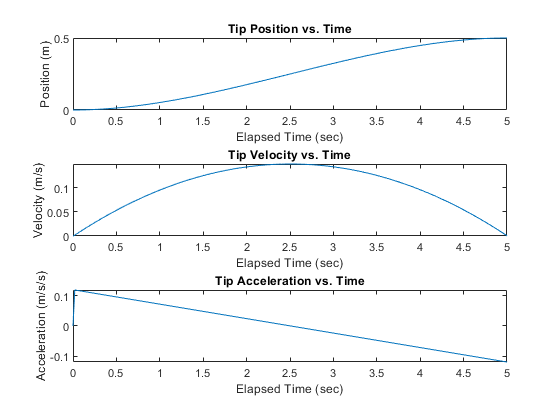

Ftip = [-10; 0; 0; 0; 0; 0];
num_JT = transpose(num_J);

% units are N*m
num_jointTorques = num_JT * Ftip

## l) plotting some trajectory generation

cubic_solns = cubicTraj(0, 5, 0, 0, 0, 0.5)

timeData = [];
posn = 0;
lastPosn = 0;
vel = 0;
lastVel = 0;
acc = 0;

posnData = [];
velData = [];
accData = [];



for ii = 0:0.01:5
    time = ii;
    posn = getInterPt(cubic_solns, time);
    vel = (posn - lastPosn)/0.01;
    acc  = (vel - lastVel)/ 0.01;
    
    lastPosn = posn;
    lastVel = vel;
    
    timeData = [timeData; time];
    posnData = [posnData; posn];
    velData = [velData; vel];
    accData = [accData; acc];
end

fig1 = figure(1);
subplot(3,1,1);
posnPlot = plot(timeData,posnData);
    xlabel('Elapsed Time (sec)');
    ylabel('Position (m)');
    title('Tip Position vs. Time');
subplot(3,1,2);
velPlot = plot(timeData,velData);
    xlabel('Elapsed Time (sec)');
    ylabel('Velocity (m/s)');
    title('Tip Velocity vs. Time');
subplot(3,1,3);
accPlot = plot(timeData,accData);
    xlabel('Elapsed Time (sec)');
    ylabel('Acceleration (m/s/s)');
    title('Tip Acceleration vs. Time');


function [coeffSolns] = cubicTraj(t0, tf, v0, vf, x0, xf)
%cubicTraj produces a trajectory using a solution to a cubic polynomial
%   consumes start time (seconds) end time (seconds),
%   start velocity (deg/s) and end velocity (deg/s)
%   start position (deg) and end position (deg)
coeffSolns = zeros(4,1,'single');

syms a0 a1 a2 a3;

eqn1 = a0 + a1*t0 + a2*t0^2 + a3*t0^3 == x0;
eqn2 = a1 + 2*a2*t0 + 3*a3*t0^2 == v0;
eqn3 = a0 + a1*tf + a2*tf^2 + a3*tf^3 == xf;
eqn4 = a1 + 2*a2*tf + 3*a3*tf^2 == vf;

[A,B] = equationsToMatrix([eqn1 eqn2 eqn3 eqn4],[a0 a1 a2 a3]);
coeffSolns = linsolve(A,B);
end

function [ thisPt ] = getInterPt( coeff_solns, thisTime )
%GETINTERPT get an interpolated point (in mm)
%   consumes a set of coeff solutions and time (in seconds)
%   produces mm the tip should be at this time
%   note: coeff_solns are the return value of cubicTraj

    a0 = coeff_solns(1);
    a1 = coeff_solns(2);
    a2 = coeff_solns(3);
    a3 = coeff_solns(4);
    
    tx = thisTime;
    
    
    thisPt = a0 + a1*tx + a2*tx^2 + a3*tx^3;
end